# TTT4135 MULTIMEDIA SIGNAL PROCESSING Assignment 1

close all;
clear;

## Part 1:

### 1: Still image compression:

#### a)

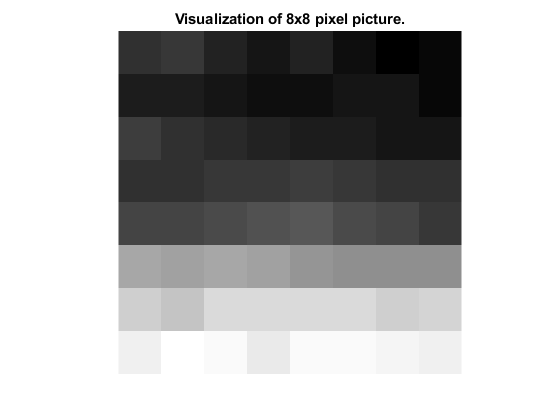

pic_mat =  [124 125 122 120 122 119 117 118
            121 121 120 119 119 120 120 118
            126 124 123 122 121 121 120 120
            124 124 125 125 126 125 124 124
            127 127 128 129 130 128 127 125
            143 142 143 142 140 139 139 139
            150 148 152 152 152 152 150 151
            156 159 158 155 158 158 157 156];
figure()
imshow(log(abs(pic_mat)),[],'InitialMagnification','fit');
title('Visualization of 8x8 pixel picture.')

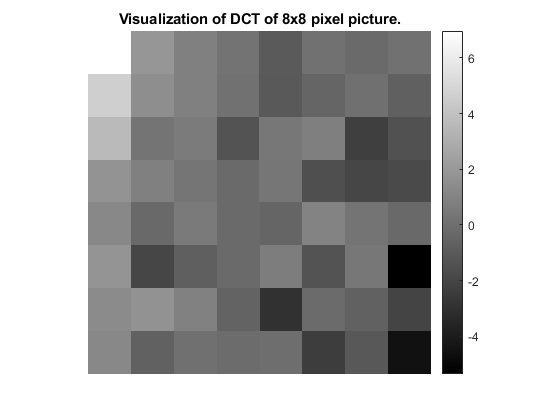


        
dct_mat = dct2(pic_mat);

figure()
imshow(log(abs(dct_mat)),[],'InitialMagnification','fit');
title('Visualization of DCT of 8x8 pixel picture.')
%colormap(gca,jet(32))
colorbar

Here we see that the highest consentration of frequencies in the picutre is in the low frequencies. Elsewhere we have some minor contributions to some of the higher frequency components.

#### b)

quant_table =  [16 11 10 16  24  40  51  61;
                12 12 14 19  26  58  60  55;
                14 13 16 24  40  57  69  56;
                14 17 22 29  51  87  80  62;
                18 22 37 56  68 109 103  77;
                24 35 55 64  81 104 113  92;
                49 64 78 87 103 121 120 101;
                72 92 95 98 112 100 103  99];

k = floor((dct_mat./quant_table) + 0.5)

k =     66     1     0     0     0     0     0     0
    -9     0     0     0     0     0     0     0
     3     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


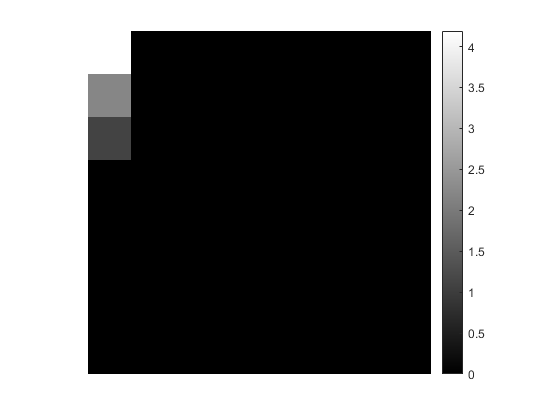

imshow(log(abs(k)),[],'InitialMagnification','fit');
colorbar

#### c)

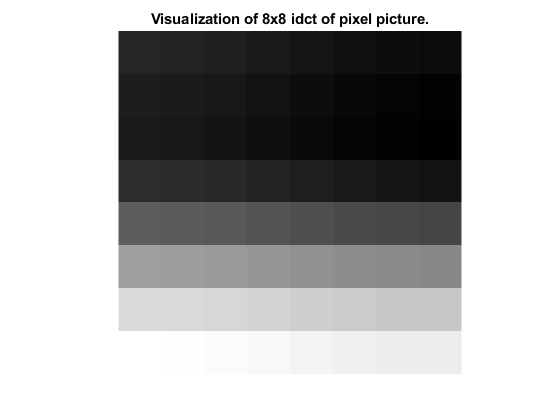

dct_mat_inv = (k.*quant_table);
idct_pic = idct2(dct_mat_inv);

figure()
imshow(log(abs(idct_pic)),[],'InitialMagnification','fit');
title('Visualization of 8x8 idct of pixel picture.')

Based on the following formulas:

$\text{PSNR}_{dB} = 10\cdot \text{log}_{10} \frac{255^2}{\sigma_e^2}$, where $\sigma_e^2 = \frac{1}{MN}\sum_{m=1}^M \sum_{n=1}^N|u(m,n)- \hat u (m,n)|^2$ (from lecture 2, slide 47)

We get the following PSNR:

M = length(pic_mat(:,1));
N = length(pic_mat(1,:));

% sigma_e2 = 0;
% for m = 1:M
%     for n = 1:N
%         sigma_e2 = sigma_e2 + abs((pic_mat(m,n) - idct_pic(m,n)));
%     end
% end
% sigma_e2 = sigma_e2/(M*N);

sigma_e = (1/(M*N))*sum(abs(pic_mat - idct_pic),'all');
% Not sure if we should use 'abs()' in the above expression, ref. L3-Visual
% compression slide 9.
PSNR = 10*log10((255^2)/(sigma_e^2));
% PSNR2 = 10*log10((255^2)/(sigma_e2^2));
fprintf('PSNR = %f\n', PSNR)%, PSNR2)

PSNR = 42.651402


### 2 - Prediction:

#### a)

Given $x(n)
$, with auto correlation given by $R_x(k) $, with $R_x(0) = \sigma_x, \text{ } R_x(1) = a, \text{ } R_x(k)=0, \text{ for}  \text{ } |k|>1.$

### 3 - Compression Basics:

#### a)

#### b)

#### c)

#### d)